Let's start by fixing the path


clear
clc

full_path='/storage/work/mjv5465/SAFE/';

restoredefaultpath;
addpath(genpath([full_path,'Data/']));
addpath(genpath([full_path,'Functions']));
addpath(genpath([full_path,'Scratch/']));
cd([full_path,'Scratch/']);

clear full_path  


## Black, Jensen, Scholes (1972) Figure 1 replication

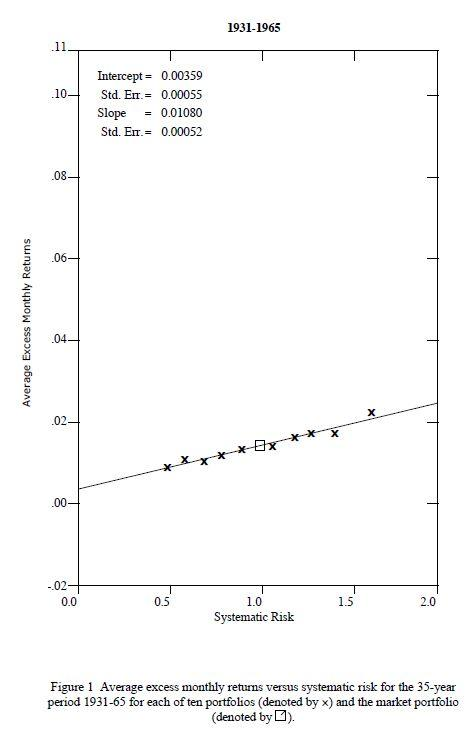

We'll start by trying to get as close to replicating Figure 1 from Black, Jensen, and Scholes (1972):

BJS was one of the first formal tests of the CAPM. The figure seeks to plot the Security Market LIne and test for the significance of the slope and intercept coefficients. To replicate the graph, let's load some variables into the workspace. 

clear
clc

load NYSE
load ret
load me
load dates
load ff

Next, we'll define a few constants that we'll need down the road. 

% Store a few constants
nMonths = size(ret, 1);
nStocks = size(ret, 2);
rollWindow = 60; 
nPtf = 10;
const = ones(rollWindow, 1);

To replicate the BJS result closely, we'll follow them and use the only NYSE stocks and an equal-weighted market index. 

ret(NYSE==0) = nan;
ewNYSEmkt = mean(ret, 2, 'omitnan') - rf;

We'll also match their sample:

% Determine the sample & initialize the betas matrix
startInd = find(dates==193012);
endInd = find(dates==196412);
bjsBetas = nan(nMonths, nStocks);

We'll also need excess returns, so we might as well store them:

xret = ret - repmat(rf, 1, nStocks);

This loop calculates the BJS betas at the end of each year:

for i = startInd:12:endInd
    % Store the returns for this rolling window
    rollWindRet = ret(i-rollWindow+1:i,:);
    
    % Find the NYSE stocks with enough data (horizontal loop index)        
    horInd = find( sum(isfinite(rollWindRet),1) >= 24 & ...
                                      NYSE(i,:) == 1);   
    nHorInd = length(horInd);
    
    % Loop over the horizontal index
    for k = 1:nHorInd
        j = horInd(k);
        
        % Store the LHS and RHS variables
        y = xret(i-rollWindow+1:i, j);
        x = [const ewNYSEmkt(i-rollWindow+1:i)];
        
        % Estimate the rgression
        res = nanols(y, x);        
        
        % Store the beta
        bjsBetas(i,j)=res.beta(2);
    end
end

Let's look at the number of stocks we get in each year:

% Table 1
ind = startInd:12:endInd;
table1Res = [floor(dates(ind)/100)+1 sum(isfinite(bjsBetas(ind,:)),2)]

table1Res =         1931         573
        1932         657
        1933         673
        1934         670
        1935         666
        1936         661
        1937         659
        1938         679
        1939         703
        1940         735


and compare them with BJS Table 1:

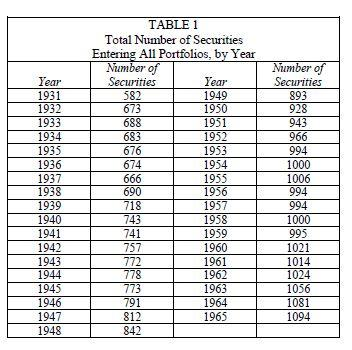

Now let's run a univariate sort based on the 10 beta portfolios:

% Get the 10 beta portfolio returns
ind = makeUnivSortInd(bjsBetas, nPtf);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'e', ...
                                       'timePeriod', [193012 196512], ...
                                       'factorModel', 1, ...
                                       'addLongShort', 0, ...
                                       'printResults', 0, ...
                                       'plotFigure', 0);

This procedure actually produces betas and average returns for the 10 portfolios:

res.factorLoadings.b

ans =     0.6850
    0.8833
    1.0469
    1.1849
    1.3054
    1.4293
    1.5808
    1.6468
    1.7704
    1.9583


res.xret

ans =     0.9788
    1.1185
    1.2494
    1.3356
    1.4200
    1.5550
    1.6397
    1.7784
    1.8444
    2.1483


However, these betas are with respect to the value-weighted market index. To get the ones with respect to the equal-weighted NYSE index:

res = runUnivSort(ret, ind, dates, me, 'weighting', 'e', ...
                                       'timePeriod', [193012 196512], ...
                                       'factorModel', ewNYSEmkt(startInd:endInd+12), ...
                                       'addLongShort', 0, ...
                                       'printResults', 0, ...
                                       'plotFigure', 0);

Now let's extract the returns and the betas:

% Store the portfolio betas
ptfBetas = res.factorLoadings.b;
meanPtfRets = res.xret/100;

and plot them against each other:

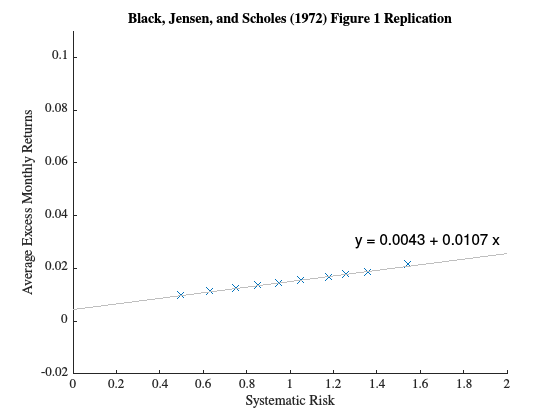


figure;
scatter(ptfBetas, meanPtfRets, 'x')
title('Black, Jensen, and Scholes (1972) Figure 1 Replication');
xlabel('Systematic Risk');
ylabel('Average Excess Monthly Returns');
ylim([-0.02 0.11]);
xlim([0 2]);
lsline;

% Print the OLS line
y = meanPtfRets;
x = [ones(nPtf, 1) ptfBetas];
tempRes = ols(y, x);
theString = sprintf('y = %.4f + %.4f x', tempRes.beta(1), tempRes.beta(2));
text(1.3, 0.03, theString, 'FontSize', 12);

Compare the results:

This was a close replication. We can do that qualitatively in fewer lines of code. The makeBetas() function in the cookbook already estimates several types of betas, and stores the results in /Data/betas.mat. 

So we can use those. For this example, I'll use what it refers to as "standard betas" (bstd). Those are calculated from rolling one year of daily data, include a Dimson correction (one day market lag), and are shrunk toward 1 with a weight of 60% on the estimate and 40% on the market beta of 1 (see Novy-Marx and Velikov (JFE, 2022) for details).

clear
clc

load betas
load ret
load dates
load me
load ff
load NYSE

% Determine the number of portfolios
nPtf = 10;

% Run the univariate sort for the 10 portfolios
ind = makeUnivSortInd(bstd, nPtf);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                       'factorModel', 1, ...
                                       'timePeriod', [199001 202112], ...
                                       'addLongShort', 0, ...
                                       'printResults', 1, ...
                                       'plotFigure', 0);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              CAPM
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt
                                           
               1    0.591    0.292    0.389
                  [ 3.17]  [ 1.73]  [10.17]
                                           
               2    0.676    0.326    0.454
                  [ 4.06]  [ 2.42]  [14.82]
                                           
               3    0.733    0.281    0.587
                  [ 4.25]  [ 2.43]  [22.39]
                                           
               4    0.792    0.294    0.646
                  [ 4.64]  [ 3.11]  [30.07]
                                           
               5    0.765    0.140    0.810
                  [ 3.70]  [ 1.35

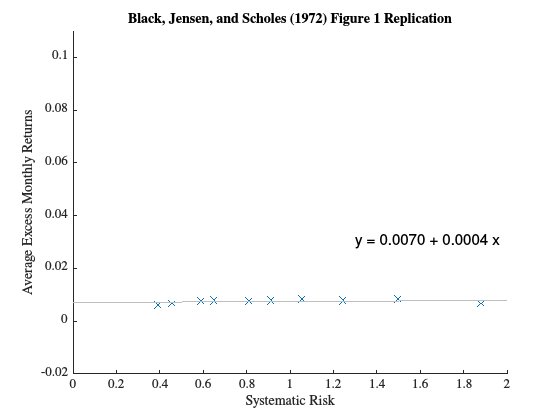


% Store the portfolio betas
ptfBetas = res.factorLoadings.b;
meanPtfRets = res.xret/100;

figure;
scatter(ptfBetas, meanPtfRets, 'x')
title('Black, Jensen, and Scholes (1972) Figure 1 Replication');
xlabel('Systematic Risk');
ylabel('Average Excess Monthly Returns');
ylim([-0.02 0.11]);
xlim([0 2]);
lsline;

% Print the OLS line
y = meanPtfRets;
x = [ones(nPtf, 1) ptfBetas];
tempRes = ols(y, x);
theString = sprintf('y = %.4f + %.4f x', tempRes.beta(1), tempRes.beta(2));
text(1.3, 0.03, theString, 'FontSize', 12);

## Fama and MacBeth (1973) replication

The original Fama and MacBeth (1973) methodology is one of the more frustrating ones to replicate. But the basic goal here is to replicate the full sample (1935-1968) result from Panel A of their Table 3:

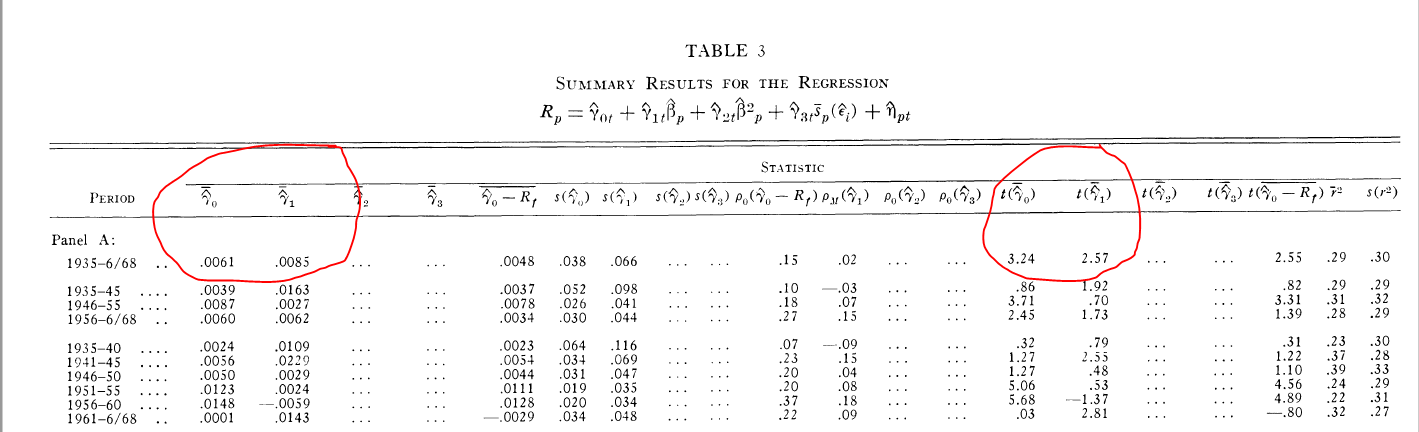

The issues come from the way FMB calculate the betas. The reason for that is the weird and ad-hoc sample selections they do. They basically divide their sample into 9 subsets:

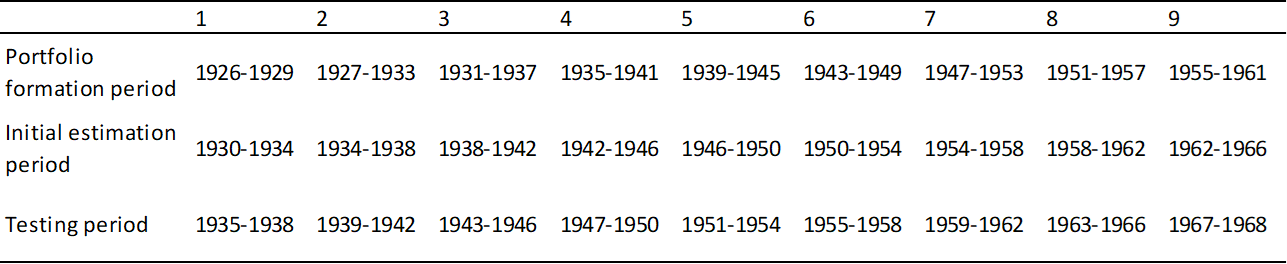

The testing procedure is as follows:

 1. For a given subset (e.g., the first one), they use the first period as portfolio formation period. That is, they estimate betas at the end of 1929 for each stock using 1926-1929 and form 20 portfolios. 

 2. Then, over the initial estimation period (1930-1934), they re-estimate the betas at the end of 1934 and average those within the portfolios to determine the portfolio betas. Here is their rationale:

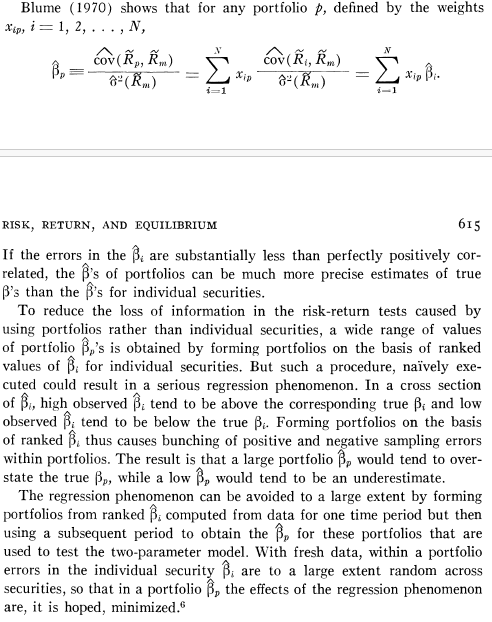

 3. They  average the betas within portfolio each month to allow for delisting and update the betas at the end of each year in the testing period (1935-38). This results in 48 cross-sectional estimations of the SML from:


$$R_{p,t} ={\hat{\gamma} }_{0t} +{\hat{\gamma} }_{1t} \;{\hat{\beta \;} }_{p,t-1} +{\hat{\eta} }_{p,t}$$


 4. Repeat above steps for all subsets and get 390 estimated SML

Here is the code that does it:

clear
clc

load NYSE
% load ret
load ret_x_dl % returns not adjusted for delisting get you closer to FF
ret = ret_x_dl;
load me
load dates
load ff

% Store a few constants
nMonths = size(ret, 1);
nStocks = size(ret, 2);
nPtf = 20;

% Remove non-NYSE firms
ret(NYSE~=1) = nan;

% Get the equal-weighted market excess return vector
ewNYSEmkt = mean(ret, 2, 'omitnan') - rf;

% Initialize portfolio assignments & individual firm betas
ind = zeros(nMonths, nStocks);
ibetas = nan(nMonths, nStocks);

% Select the sample
startInd = find(dates==192912);
endInd = find(dates==196112);

for i = startInd:48:endInd

    % Determine the start of the initial estimation period
    s = max(2,i-83);
    
    % Potrfolio formation period
    pfPeriod = s:i;
    % Initial estimation period
    iePeriod = i+1:i+60;
    % Testing period
    tPeriod = i+60:i+107; 
    
    % Find stocks with returns for more than 48 months in the portfolio
    % formation period and for 60 months in the initial estimation period
    hor_ind = find(sum(isfinite(ret(pfPeriod,:)), 1) >= 48 & ...
                   sum(isfinite(ret(iePeriod,:)), 1) >= 60   );
    
    % Initialize the portfolio formation betas
    ptf_formation_betas = nan(1, nStocks);
    const = ones(size(rf(pfPeriod)));
    for k = 1:length(hor_ind)
        j = hor_ind(k);
        y = ret(pfPeriod, j) - rf(pfPeriod);
        x = [const ewNYSEmkt(pfPeriod)];
        res1 = nanols(y, x);
        ptf_formation_betas(1, j) = res1.beta(2);
    end
    % Assign the portfolio rankings for the testing period    
    ptfRankings = makeUnivSortInd(ptf_formation_betas, nPtf);
    ind(tPeriod, :) = repmat(ptfRankings, 48, 1);
    
    % Loop over the end-of-years in the testing period, where we need to
    % reestimate the betas 
    for e=i+(60:12:96)
        est_betas = nan(1, nStocks);
        for k = 1:length(hor_ind)
            j = hor_ind(k);
            y = ret(i+1:e,j)-rf(i+1:e);
            x = [ones(size(rf(i+1:e))) ewNYSEmkt(i+1:e)];
            res1 = nanols(y, x);
            est_betas(j) = res1.beta(2);
        end
        ibetas(e:e+11, :) = repmat(est_betas,12,1);    
    end    
end

% Clean up the individual firm betas and the portfolio indicator matrix 
indToDrop = isnan(lead(ret, 1, nan));
ibetas(indToDrop) = nan;
ind(indToDrop) = 0;

% Initialize the portfolio beta and return matrices
ptf_betas = nan(nMonths, nPtf);
ptf_ret   = nan(nMonths, nPtf);

% Calculate the average portfolio betas and returns
for i = 1:nPtf
    temp_betas = ibetas;
    temp_betas(ind~=i) = nan;
    ptf_betas(:, i) = mean(temp_betas, 2, 'omitnan');
    temp_ret = ret;
    temp_ret(ind~=i) = nan;
    ptf_ret(:, i) = mean(temp_ret, 2, 'omitnan');
end

y = 100 * ptf_ret;
x = ptf_betas;
res = runFamaMacBeth(y, x, dates, 'minObs', 10, ...
                                  'timePeriod', [193501 196812]);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        0.561        2.950 
                    var 1        0.886        2.623 

---------------------------------------------------------------------- 


Again, we can do that with a couple of lines if we don't care about exact replication:

clear
clc

load ret
load dates
load betas

runFamaMacBeth(100*ret, bstd, dates, 'timePeriod', [193501 196812]);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.174        7.194 
                    var 1        0.294        0.968 

---------------------------------------------------------------------- 


## Campbell-Lo-MacKinlay Table 5.3 Replication

The goal here is to qualitatively replicate the headline GRS result in Table 5.3 from CLM:

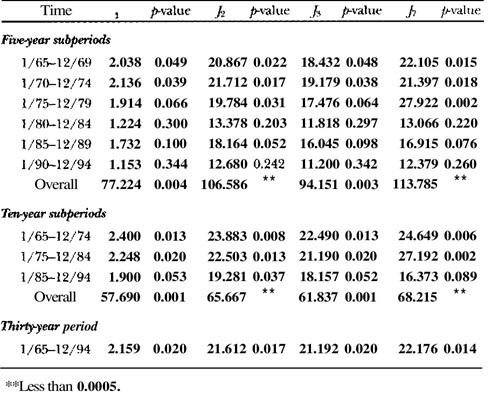

This is actually quite easy in the code, because the bivariate sort function (runBivSort) has a GRS test built into it. 

Let's start by loading the necessary variables:

clear
clc

load ret
load me
load dates
load ff
load NYSE
load exchcd

CLM use only NYSE and AMEX stocks (CRSP exchange codes 1 and 2):

me(exchcd~=1 & exchcd~=2) = nan;

Choose the number of portfolios:

nPtf = 10;

Following CLM, sort into the 10 portfolios based on market equity:

ind = makeUnivSortInd(me, nPtf);

Turn the bivariate sort function with the univariate sort index. This is a trick, since the bivariate sort index is usually used for double sorts (e.g., 5x5 Fama-French style sorts). However, the benefit of it is that it also returns results for the all underlying portfolios and includes a GRS test:

[res, ~] = runBivSort(ret, ind, 5, 2, dates, me, 'timePeriod', [196412 199412], ...
                                                 'factorModel', 1, ...
                                                 'printResults', 2);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              CAPM
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt
                                            
               1    1.127    0.674    1.236 
                  [ 2.38]  [ 1.81]  [14.99] 
                                            
               2    0.690    0.242    1.220 
                  [ 1.72]  [ 0.88]  [20.02] 
                                            
               3    0.643    0.192    1.228 
                  [ 1.74]  [ 0.85]  [24.71] 
                                            
               4    0.673    0.214    1.253 
                  [ 1.90]  [ 1.11]  [29.51] 
                                            
               5    0.664    0.196    1.276 
                  [

The results structure has the GRS results:

res.grsFstat(1)

ans = 3.0781

res.grsPval(1)

ans = 9.1215e-04

We can also code the test ourselves. Here is the statistic:


$$J_1 =\left(\frac{T-N-K}{N}\right){\left\lbrack 1+{\left(\frac{\hat{\mu \;} }{\hat{\sigma} }\right)}^2 \right\rbrack }^{-1} {\hat{\alpha} }^{\prime } {\hat{\Sigma} }^{-1} \hat{\alpha} \sim F\left(N,T-N-K\right)$$


Let's get the portfolio returns from the results structure above. We'll skip the first line, because it correspond the the first month we're sorting in (196412):

ptfRets = res.pret(2:end, :);

Next, let's store a few constants and the relevant dates indices:

s = find(dates==196501);
e = find(dates==199412);
N = nPtf;
T = size(ptfRets, 1);
K = 1;

Store the alphas, residuals, and the degrees of fredom:

alpha = res.alpha'/100;
resid = res.resid(2:end, :);
df = [N, T - N - K];

Calculate the numerator:

SigmaInv = cov(resid)^(-1);
numer = alpha * SigmaInv * alpha';

And the denominator:

mu_m = mean(mkt(s:e));
sigma_m = std(mkt(s:e));
denom = 1 + (mu_m/sigma_m)^2;

Now we can get the F-statistic and get its p-value:

fStat = (df(2)/df(1)) * numer / denom

fStat = 3.0781

pVal = 1 - fcdf(fStat, df(1), df(2))

pVal = 9.1215e-04

## Fama and French (1992) Table III replication

Table III of Fama and French (1992) has Fama-MacBeth estimation results that are a much more popular use of the technique in the anomaly literature. It reports average slopes and t-statistics from month-by-month regressions of stocks returns on characteristics including beta, size, book-to-market, and equity:

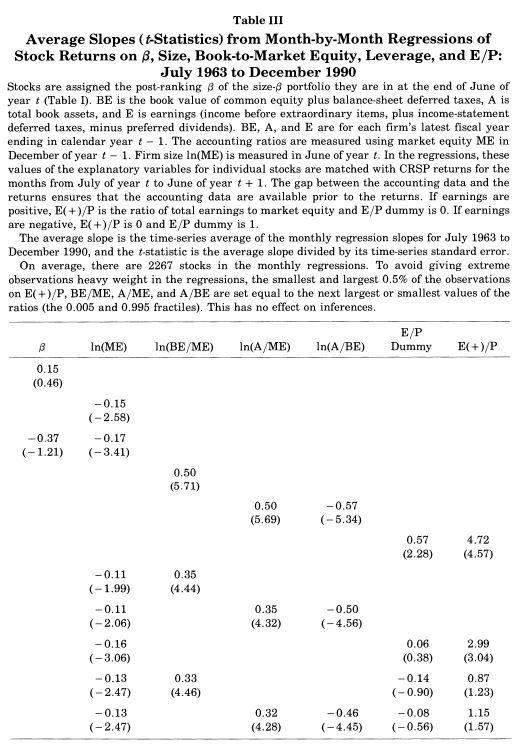

To replicate it, the most annoying thing is their beta estimation, which, at the end of the day, doesn't really matter all that much. So, after loading the variables and excluding financials:

clear
clc

load ret
load ff
load me
load dates
load bm
load AT
load BE
load FinFirms

% Get rid of financials. 
me(FinFirms==1) = nan;
ret(FinFirms==1) = nan;

you can either follow their procedure for estimating betas:

% Store a few constants
nMonths = size(ret, 1);
nStocks = size(ret, 2);
rollWindow = 60;

% Store the excess returns
xret = ret - repmat(rf, 1, nStocks);

% store a constant for the beta estimation
const = ones(rollWindow,1);

% Initialize individual stock betas
betas = nan(size(ret));

% Determine the sample
startDate = find(dates==196306);
endDate = find(dates==199012);

for i = startDate:12:endDate
    % Store this rolling window's returns
    thisRollWindRet = ret(i-rollWindow+1:i,:);
    
    % calculate the number of finite return observations  
    numRetObs = sum(isfinite(thisRollWindRet), 1);
    
    % Find which stocks have enough (>=24 obs) data (horizontal index)
    horInd = find(numRetObs >= 24);
    
    % Loop over the horizontal index
    for k = 1:length(horInd)
        j = horInd(k);
        
        % Estimate the regression (include a market lag)
        y = xret(i-rollWindow+1:i, j);
        x = [const mkt(i-rollWindow+1:i) mkt(i-rollWindow:i-1)];
        res = nanols(y, x);
        
        % Store the betas 
        betas(i,j) = res.beta(2) + res.beta(3);
    end       
end

% Use market cap only at the end of June
tempME = me;
monthInd = dates - 100*floor(dates/100);
tempME(monthInd ~= 6, :) = nan;

% Create the 10x10 size x beta portfolios
ind = makeBivSortInd(tempME, 10, betas, 10, 'sortType', 'conditional');  
[res, ~] = runBivSort(ret, ind, 10, 10, dates, me, 'weighting', 'e', ...
                                                   'timePeriod', [196306 199012], ...
                                                   'printResults', 0, ...
                                                   'factorModel', 1); 
                                              
% Estimate the full-sample portfolio betas & assign them to the individual stocks
const = ones(endDate-startDate+1, 1);
betas = nan(size(ret));
for i = 1:100    
    y = res.pret(:,i) - rf(startDate:endDate);
    x = [const mkt(startDate:endDate) mkt(startDate-1:endDate-1)];
    tempRes = nanols(y, x);
    betas(ind==i) = tempRes.beta(2) + tempRes.beta(3);
end

or use some of the pre-estimated ones by the cookbook:

load betas
betas = bstd; 

Then, to replicate first few rows of Table III, we need to construct the leverage variables and use the runFamaMacBeth() function::

% Create the leverage variables
am = AT./lag(me,6,nan);
am(am<=0) = nan;

ab = AT./BE;
ab(ab<=0) = nan;

% Estimate the Fama-MacBeths
res = runFamaMacBeth(100*ret, [betas],                       dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.502        6.598 
                    var 1       -0.383       -1.439 

---------------------------------------------------------------------- 


res = runFamaMacBeth(100*ret, [log(me)],                     dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5, ...
                                                                    'labels', {'Const','log(me)'});

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                 Const           1.629        3.456 
                 log(me)        -0.139       -2.416 

---------------------------------------------------------------------- 


res = runFamaMacBeth(100*ret, [betas log(me)],               dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.834        5.374 
                    var 1       -0.226       -0.812 
                    var 2       -0.135       -2.281 

---------------------------------------------------------------------- 


res = runFamaMacBeth(100*ret, [log(bm)],                     dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.318        4.185 
                    var 1        0.468        5.642 

---------------------------------------------------------------------- 


res = runFamaMacBeth(100*ret, [log(me) log(bm)],             dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.758        3.788 
                    var 1       -0.116       -2.027 
                    var 2        0.343        4.333 

---------------------------------------------------------------------- 


res = runFamaMacBeth(100*ret, [log(am) log(ab)],             dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.426        4.783 
                    var 1        0.464        5.529 
                    var 2       -0.587       -6.586 

---------------------------------------------------------------------- 


res = runFamaMacBeth(100*ret, [log(me) log(am) log(ab)],     dates, 'timePeriod', [196306 199012], ...
                                                                    'winsorTrimPctg', 0.5);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.914        4.290 
                    var 1       -0.120       -2.114 
                    var 2        0.322        4.043 
                    var 3       -0.506       -5.506 

---------------------------------------------------------------------- 


Compare with:

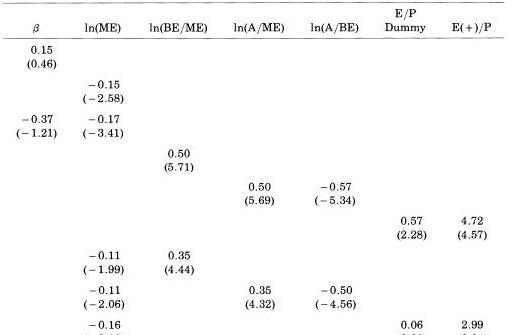

## Fama and French (1993), Table 9c replication


clear
clc

load ret_x_dl % returns not adjusted for delisting get you closer to FF
ret = ret_x_dl;
% load ret
load me
load dates
load NYSE
load bm
load ff
load FinFirms

% Get rid of nonpositive bm
bm(bm<=0) = nan;

% Easy way - use the built-in GRS function that is called by the runBivSort
ind = makeBivSortInd(me, 5, bm, 5, 'sortType', 'unconditional', ...
                                   'breaksFilterInd', NYSE);  
                               
[resCAPM, ~] = runBivSort(ret, ind, 5, 5, dates, me, 'timePeriod', [192512 202112], ...
                                                     'factorModel', 1, ...
                                                     'printResults', 1);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              CAPM
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt
                                            
               1    0.605   -0.520    1.622 
                  [ 1.70]  [-2.07]  [34.81] 
                                            
               2    0.725   -0.267    1.431 
                  [ 2.49]  [-1.44]  [41.55] 
                                            
               3    0.996    0.053    1.360 
                  [ 3.79]  [ 0.35]  [47.75] 
                                            
               4    1.127    0.249    1.266 
                  [ 4.61]  [ 1.75]  [47.72] 
                                            
               5    1.367    0.408    1.383 
                  [

[resFF3, ~] = runBivSort(ret, ind, 5, 5, dates, me, 'timePeriod', [192512 202112], ...
                                                    'factorModel', 3, ...
                                                    'printResults', 1);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 3-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml
                                                                
               1    0.605   -0.705    1.286    1.467    0.381   
                  [ 1.70]  [-3.37]  [30.74]  [21.33]  [ 6.31]   
                                                                
               2    0.725   -0.420    1.111    1.504    0.232   
                  [ 2.49]  [-3.40]  [44.94]  [36.98]  [ 6.48]   
                                                                
               3    0.996   -0.145    1.046    1.242    0.503   
                  [ 3.79]  [-1.64]  [59.18]  [42.75]  [19.70]   
                    

                                                
fprintf('F-statistic for CAPM is %2.4f, and for FF3 is %2.4f.\n',resCAPM.grsFstat(1), resFF3.grsFstat(1));

F-statistic for CAPM is 3.0606, and for FF3 is 2.8878.
